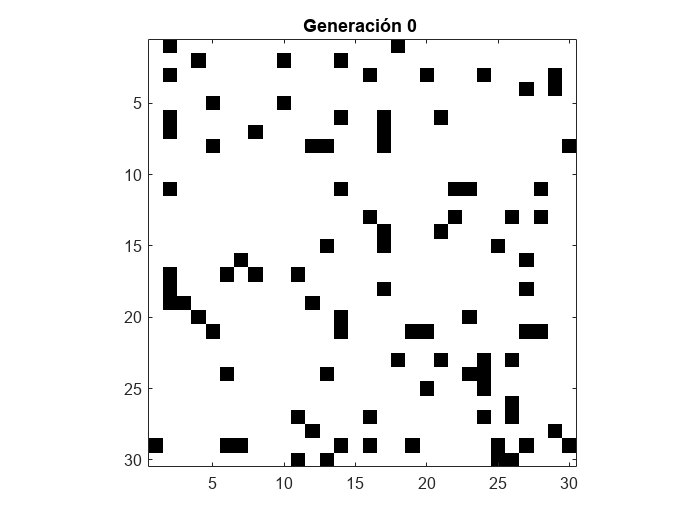

clc;
clear;

sizeT = 30; % Tamaño del tablero

probabilidad = 0.1;
%tablero =
%iniciales = round(probabilidad*(sizeT*sizeT));

tablero = rand(sizeT) < probabilidad;


%tablero = randi([0,1], sizeT, sizeT);
figure;
imagesc(tablero);
    %colormap([0 0 0; 1 1 1]);
colormap([1 1 1; 0 0 0]);% Blanco para células muertas, negro para células vivas
axis square;
title('Generación 0 ');

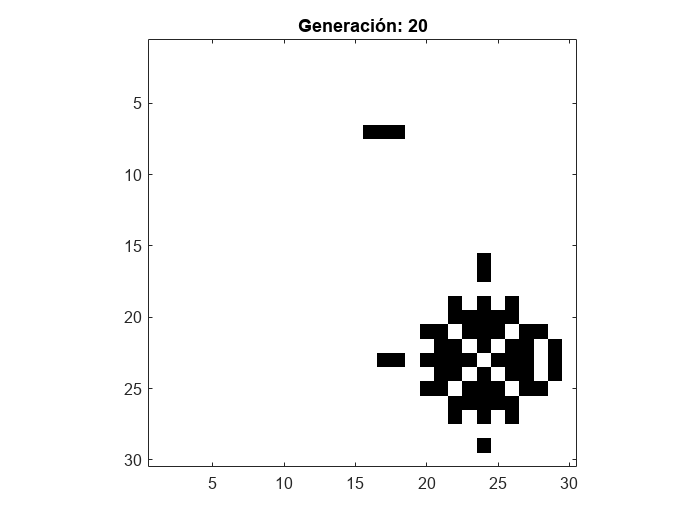



figure;

generaciones = 20; % Número de generaciones a simular

for generacion = 1:generaciones

    imagesc(tablero);
    %colormap([0 0 0; 1 1 1]);
    colormap([1 1 1; 0 0 0]);% Blanco para células muertas, negro para células vivas
    title(['Generación: ' num2str(generacion)]);
    axis square;
    drawnow; % Actualizar la visualización
    
    %nuevo_tablero = ones(size(tablero));
    nuevo_tablero = zeros(size(tablero));
    
    for x = 2: sizeT -1
        for y = 2: sizeT -1
            vecinos = tablero(x-1,y-1) + tablero(x,y-1) + tablero(x+1,y-1) + tablero(x-1,y) + tablero(x+1,y) + tablero(x-1,y+1) + tablero(x,y+1) + tablero(x+1,y+1);

            %  Reglas del Juego de la Vida
            if tablero(x, y) == 1 % Célula viva
                if vecinos < 2 || vecinos > 3
                    nuevo_tablero(x, y) = 0; % Muere por soledad o superpoblación
                else
                    nuevo_tablero(x, y) = 1; % Sobrevive
                end
            else % Célula muerta
                if vecinos == 3
                    nuevo_tablero(x, y) = 1; % Nace debido a la reproducción
                end
            end

        end
    end

    tablero = nuevo_tablero;
    
    pause(0.5);    % Pausa para visualización (opcional)
end